clear; close all;

Treatment = "ChemoUniM2";
Protocol  = "ThreeFPHoldSRT";
Subject   = "Chester";

Drives = string(char('A':'Z')');
for i = 1:26
    folder_i = Drives(i)+":\OneDrive";
    if isfolder(folder_i)
        WorkFolder = fullfile(folder_i, "YuLab\GPS_Project\Scripts");
    end
end

DataFolder = fullfile(WorkFolder, "Data", Treatment, Protocol, Subject);

FigFolder  = fullfile(WorkFolder, "Figures", Treatment, Protocol, Subject);
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

DataFile = dir(fullfile(DataFolder, "*Traj*.mat"));
if isempty(DataFile)
    error('No traj data files here');
elseif length(DataFile)>1
    error('More than one traj data file')
end

load(fullfile(DataFolder, DataFile.name));


feature = ["AngleHead", "PosXHead", "PosYHead"];

Trace_origin = obj.gather_trace(feature);
% Array_origin = obj.trace2array(Trace_origin);
% [coeff,Array_pca,latent,tsquared,explained,mu] = pca(zscore(Array_origin, [], 1));
% p = cumsum(explained);
% n = find(p>95, 1);
% 
% Trace_pca = obj.array2trace(Array_pca, obj.TimeFromIn);
% Mat_origin = obj.trace2mat(Trace_pca, obj.TimeFromIn, obj.TimeMatIn);



Time_origin = obj.TimeMatIn;

T = 1;
% Time = 100:20:T*1000;
% n_time = length(Time);
% time_bins = [0 Time];
% 
% Mat = zeros(size(Mat_origin, 1), n_time, size(Mat_origin, 3));
% for i = 1:n_time
%     id = Time_origin > time_bins(i) & Time_origin <= time_bins(i+1);
%     Mat(:, i, :) = mean(Mat_origin(:, id, :), 2, 'omitnan');
% end
% 
Info = obj.TrialInfo;
% 
% Mat_Control = Mat(Info.Stage==1 & Info.Label=="Control" & Info.FP>=T & Info.HD>=T, :, 1:n);
% Mat_Chemo   = Mat(Info.Stage==1 & Info.Label=="Chemo" & Info.FP>=T & Info.HD>=T, :, 1:n);
% 
% Info_Control = Info(Info.Stage==1 & Info.Label=="Control" & Info.FP>=T & Info.HD>=T, :);
% Info_Chemo   = Info(Info.Stage==1 & Info.Label=="Chemo" & Info.FP>=T & Info.HD>=T, :);
% 
% x_control = Info_Control.PortCorrect;
% x_chemo   = Info_Chemo.PortCorrect;


% p_control = zeros(1, n_time);
% p_chemo   = zeros(1, n_time);
% 
% for i = 1:n_time
%     y_control = squeeze(Mat_Control(:, i, :));
%     y_chemo   = squeeze(Mat_Chemo(:, i, :));
% 
%     mdl_control = fitglm(y_control, x_control-1, 'Distribution','binomial', 'Link', 'logit');
%     p_control(i) = mdl_control.coefTest;
% 
%     mdl_chemo = fitglm(y_chemo, x_chemo-1, 'Distribution','binomial', 'Link', 'logit');
%     p_chemo(i) = mdl_chemo.coefTest;
% end
% 
% figure(); hold on;
% plot(Time, p_control)
% plot(Time, p_chemo)
% yline(0.05 / n_time)
% ylim([0 1])
% xlim([0 1500])


%%
Trace_z = obj.normalize_trace(Trace_origin(Info.Stage==1 & Info.FP>=T & Info.HD>=T), 'zscore');
Time_z = obj.TimeFromIn(Info.Stage==1 & Info.FP>=T & Info.HD>=T);
info_z = Info(Info.Stage==1 & Info.FP>=T & Info.HD>=T, :);

Mat_z = obj.trace2mat(Trace_z, Time_z, 220:20:1000*T);
Mat_z_cat = reshape(Mat_z, size(Mat_z, 1), []);

% [coeff,score,latent,tsquared,explained,mu] = pca(Mat_z_cat);
% score = tsne(Mat_z_cat, 'NumDimensions', 3);


% fig = figure(11); clf(11);
% set(fig, 'visible', 'on');
% 
% ax = axes('NextPlot', 'add');
% 
% id = find(info_z.Label=="Control" & info_z.PortCorrect==1);
% for i = 1:length(id)
%     scatter3(score(id(i),1), score(id(i),2), score(id(i),3), 'r', 'filled', 'MarkerFaceColor', GPSColor.PortL, 'MarkerFaceAlpha', .4)
% end
% 
% id = find(info_z.Label=="Chemo" & info_z.PortCorrect==1);
% for i = 1:length(id)
%     scatter3(score(id(i),1), score(id(i),2), score(id(i),3), 'r', 'MarkerEdgeColor', GPSColor.PortL, 'MarkerEdgeAlpha', .4, 'LineWidth', 1)
% end
% 
% id = find(info_z.Label=="Control" & info_z.PortCorrect==2);
% for i = 1:length(id)
%     scatter3(score(id(i),1), score(id(i),2), score(id(i),3), 'r', 'filled', 'MarkerFaceColor', GPSColor.PortR, 'MarkerFaceAlpha', .4)
% end
% 
% id = find(info_z.Label=="Chemo" & info_z.PortCorrect==2);
% for i = 1:length(id)
%     scatter3(score(id(i),1), score(id(i),2), score(id(i),3), 'r', 'MarkerEdgeColor', GPSColor.PortR, 'MarkerEdgeAlpha', .4, 'LineWidth', 1)
% end
% 
% ax.Children = ax.Children(randperm(length(ax.Children)));
% 
% 

% n_dim = find(cumsum(explained)>90, 1);
% n_trace = size(score, 1);
% 
% id_train = randperm(n_trace, floor(n_trace/2))';
% id_test = setdiff(1:n_trace, id_train)';
% 
% y_train = info_z.Label(id_train);
% x_train = score(id_train, 1:n_dim);
% y_test = info_z.Label(id_test);
% x_test = score(id_test, 1:n_dim);
% 
% cvp = cvpartition(y_train,'KFold', 10);
% Mdl_cv = fitcdiscr(x_train, y_train, "CrossVal", "on", "CVPartition", cvp);
% Acc_cv = 1-kfoldLoss(Mdl_cv, "Mode", "individual");
% 
% %
% Mdl = fitcsvm(x_train, y_train);
% 
% y_pred = string(Mdl.predict(x_test));
% 
% sum(y_pred==y_test) / length(y_test)
% sum(y_pred=="Control" & y_test=="Chemo") / sum(y_test=="Chemo")
% sum(y_pred=="Chemo" & y_test=="Control") / sum(y_test=="Control")
% 
% id_chemo_wrong = id_test(y_pred=="Control" & y_test=="Chemo");
% id_chemo_correct = id_test(y_pred=="Chemo" & y_test=="Chemo");
% id_control_correct = id_test(y_pred=="Control" & y_test=="Control");
% 

% fig = figure(13); clf(13);
% set(fig, 'visible', 'on');
% 
% ax = axes('NextPlot', 'add');
% 
% for i = 1:length(id_chemo_correct)
%     if info_z.PortCorrect(id_chemo_correct(i))==1
%         c = GPSColor.PortL;
%     else
%         c = GPSColor.PortR;
%     end
%     scatter(score(id_chemo_correct(i),1), score(id_chemo_correct(i),2), 'r', 'filled', 'MarkerFaceColor', c, 'MarkerFaceAlpha', .4)
% end
% 
% for i = 1:length(id_chemo_wrong)
%     if info_z.PortCorrect(id_chemo_wrong(i))==1
%         c = GPSColor.PortL;
%     else
%         c = GPSColor.PortR;
%     end
%     scatter(score(id_chemo_wrong(i),1), score(id_chemo_wrong(i),2), 'r', 'MarkerEdgeColor', c, 'MarkerEdgeAlpha', .4, 'LineWidth', 1)
% end
% 
% ax.Children = ax.Children(randperm(length(ax.Children)));

% 
% fig = figure(17); clf(fig);
% set(fig, 'Visible', 'on');
% hold on;
% % for i = 1:length(id_wrong_l)
% %     plot(Trace_z{id_wrong_l(i)}(1,:), 'Color', [1 0 0 .2])
% % end
% for i = 1:length(id_chemo_correct)
%     id_this = id_chemo_correct(i);
%     t = Time_z{id_this};
%     fp = find(t>0 & t<T*1000);
%     if info_z.PortCorrect(id_this)==1
%         c = GPSColor.PortL;
%     else
%         c = GPSColor.PortR;
%     end
%     plot(t(fp), Trace_z{id_this}(2,fp), 'Color', [c .2], 'LineWidth', 1.2)
% end
% 

% fig = figure(18); clf(fig);
% set(fig, 'Visible', 'on');
% hold on;
% % for i = 1:length(id_wrong_l)
% %     plot(Trace_z{id_wrong_l(i)}(1,:), 'Color', [1 0 0 .2])
% % end
% for i = 1:length(id_chemo_wrong)
%     id_this = id_chemo_wrong(i);
%     t = Time_z{id_this};
%     fp = find(t>0 & t<T*1000);
%     if info_z.PortCorrect(id_this)==1
%         c = GPSColor.PortL;
%     else
%         c = GPSColor.PortR;
%     end
%     plot(t(fp), Trace_z{id_this}(2,fp), 'Color', [c .2], 'LineWidth', 1.2)
% end
% 

% p_1 = zeros(100,50);
% p_2 = zeros(100,50);
% 
% n_1 = zeros(100,1);
% n_2 = zeros(100,1);
% 
% id = 1:n_trace;
% y = info_z.Label;
% id_control = id(y=="Control");
% id_chemo = id(y=="Chemo");
% n = min([100 length(id_control) length(id_chemo)]);
% 
% for i = 1:50
%     loc = cellfun(@(x, t) x(:, find(t<1000-20*(50-i), 1, 'last'))', Trace_z, Time_z, 'UniformOutput', false);
%     loc = cell2mat(loc);
% 
%     for s = 1:100
% %         id_control_this = find; % id_control_correct; % (randperm(length(id_control_correct), 50))
%         id_control_this = id_control(randi(length(id_control), 1, n));
%         %     mdl_1 = fitglm(loc(id_control_this, :), info_z.PortCorrect(id_control_this)-1, 'Distribution','binomial', 'Link', 'logit');
%         [~, p_1(s, i)] = manova1(loc(id_control_this, :), info_z.PortCorrect(id_control_this)-1);
% 
%         %         id_chemo_this = find(info_z.Label=="Chemo");% id_chemo_correct;
%         id_chemo_this = id_chemo(randi(length(id_chemo), 1, n));
%         %     mdl_2 = fitglm(loc(id_chemo_this, :), info_z.PortCorrect(id_chemo_this)-1, 'Distribution','binomial', 'Link', 'logit');
%         [~, p_2(s, i)] = manova1(loc(id_chemo_this, :), info_z.PortCorrect(id_chemo_this)-1);
%     end
% end
% 
% for i = 1:100
%    d_1 = diff([0 p_1(i,:)<0.01 0]);
%    start_1 = find(d_1==1);
%    end_1   = find(d_1==-1);
%    l_1 = end_1 - start_1;
%    i_1 = find(l_1>=5, 1, 'first');
%    if ~isempty(i_1)
%        n_1(i) = start_1(i_1);
%    else
%        n_1(i) = 50;
%    end
% 
%    d_2 = diff([0 p_2(i,:)<0.01 0]);
%    start_2 = find(d_2==1);
%    end_2   = find(d_2==-1);
%    l_2 = end_2 - start_2;
%    i_2 = find(l_2>=5, 1, 'first');
%    if ~isempty(i_2)
%        n_2(i) = start_2(i_2);
%    else
%        n_2(i) = 50;
%    end
% end
% 
% figure('visible', 'on'); hold on;
% plot(220:20:1200, mean(p_1));
% % [~, i_control] = find(p_1<.05/50, 1);
% % t_control = 1200-20*(50-i_control)
% plot(220:20:1200, mean(p_2));
% % [~, i_chemo] = find(p_2<.05/50, 1);
% % t_chemo = 1200-20*(50-i_chemo)
% 
% yline(.01, 'LineStyle', ':')
% ylim([0 .5])
% 
% mean(n_1)
% mean(n_2)


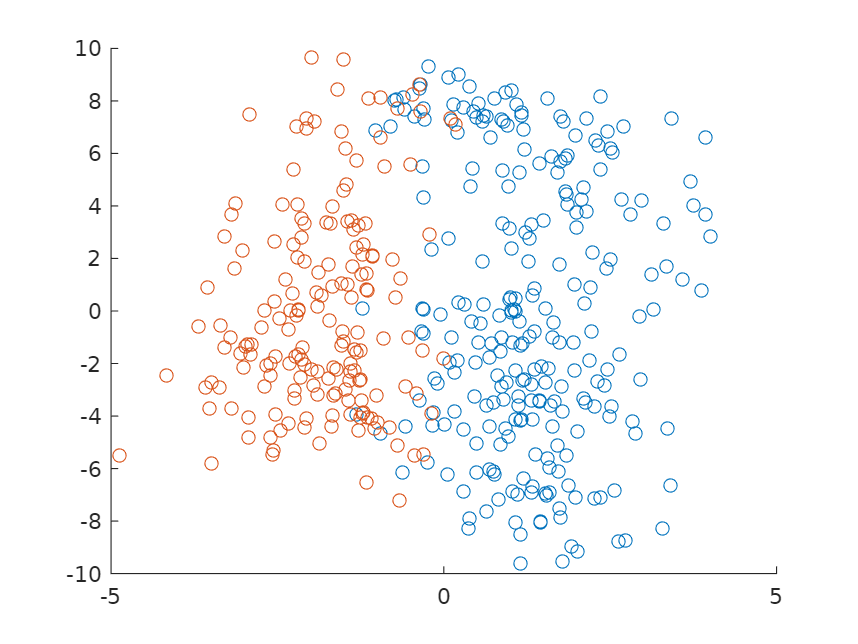

y = info_z.Label;
p = info_z.PortCorrect;
rt = info_z.RT;
rt_cat = zeros(length(rt), 1);
rt_prc = prctile(rt, 10:10:100);
rt_cat(rt<=rt_prc(1)) = 1;
for i = 2:length(rt_prc)
    rt_cat(rt>rt_prc(i-1) & rt<=rt_prc(i)) = i;
end

id_ctrl = find(y=="Control" & ~isnan(rt));
id_train = id_ctrl; % (randperm(length(id_ctrl), round(length(id_ctrl)*.9)))
id_test = id_train; % setdiff(id_ctrl, id_train);
[mapped_train, mapping] = compute_mapping([p(id_train) Mat_z_cat(id_train,:)], 'LDA', 1);

d = mean(mapped_train(p(id_train)==1)) - mean(mapped_train(p(id_train)==2));
if d<0
    mapping.M = -mapping.M;
end
mapping.null = null(mapping.M');
mapped_null = Mat_z_cat(id_test,:) * mapping.null;

mapped_train = (Mat_z_cat(id_train,:)-mapping.mean) * mapping.M;
mapped_test = (Mat_z_cat(id_test,:)-mapping.mean) * mapping.M;

m_pca = pca(mapped_null, 1);

p_test = p(id_test);
rt_test = rt(id_test);
figure(); hold on;
scatter(mapped_test(p_test==1), m_pca(p_test==1))
scatter(mapped_test(p_test==2), m_pca(p_test==2))


mean(mapped_test(p_test==1))

ans = 1.2613

mean(mapped_test(p_test==2))

ans = -1.8275

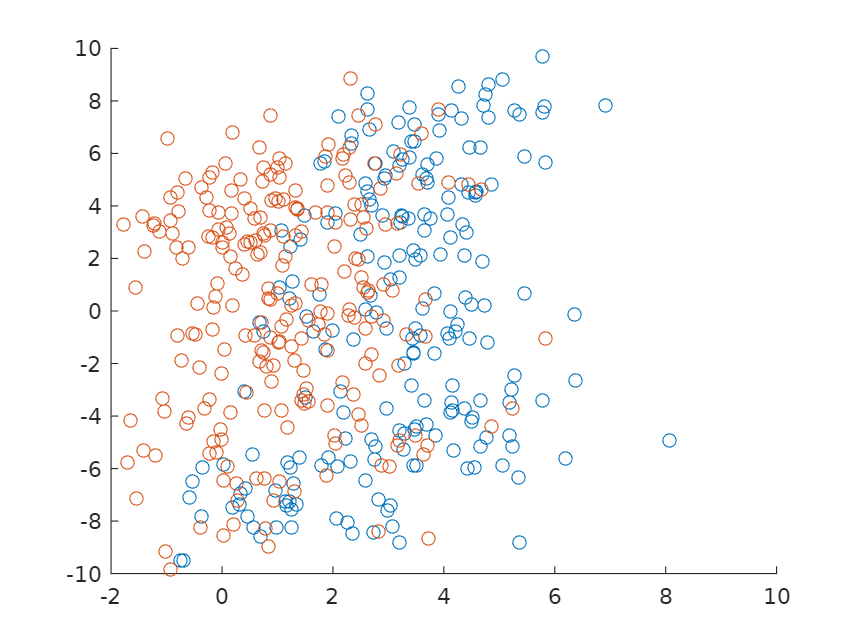

m = (Mat_z_cat(y=="Chemo", :)-mapping.mean) * mapping.M;
m_2 = pca((Mat_z_cat(y=="Chemo", :)-mapping.mean) * mapping.null, 1);

p_chemo = p(y=="Chemo");
figure(); hold on;
scatter(m(p_chemo==1), m_2(p_chemo==1))
scatter(m(p_chemo==2), m_2(p_chemo==2))



mean(m(p_chemo==1))

ans = 3.1554

mean(m(p_chemo==2))

ans = 1.1186

## Coding direction

id = perf=="Correct" & fp>=1;

a = cellfun(@(x, t) x(find(t<1000, 40, 'last')), obj.AngleHead, obj.TimeFromIn, 'UniformOutput', false);
b = cellfun(@(x, t) x(find(t<1000, 40, 'last')), obj.PosXHead, obj.TimeFromIn, 'UniformOutput', false);
c = cellfun(@(x, t) x(find(t<1000, 40, 'last')), obj.PosYHead, obj.TimeFromIn, 'UniformOutput', false);

a = cell2mat(a(id));
b = cell2mat(b(id));
c = cell2mat(c(id));

a = zscore(a, 0, 'all');
b = zscore(b, 0, 'all');
c = zscore(c, 0, 'all');
x = cat(3, a, b, c);

y = port_plan(id);
lb = label(id);

x_l = x(y==1 & lb=="Control", :, :);
x_r = x(y==2 & lb=="Control", :, :);

coding_dir = median(x_l, 1) - median(x_r, 1);
coding_dir = squeeze(coding_dir);
coding_dir = mean(coding_dir)

proj = zeros(length(x), 40);

for i = 1:length(proj)
    for j = 1:40
        proj(i, j) = dot(squeeze(x(i,j,:)), coding_dir') / norm(coding_dir');
    end
end

figure(); hold on;
plot(mean(proj(y==1 & lb=="Control", :)), 'Color', GPSColor.PortL)
plot(mean(proj(y==2 & lb=="Control", :)), 'Color', GPSColor.PortR)
std(proj(y==1 & lb=="Control", :))
std(proj(y==2 & lb=="Control", :))

plot(mean(proj(y==1 & lb=="Chemo", :)), 'Color', GPSColor.PortL, 'LineStyle', ':')
plot(mean(proj(y==2 & lb=="Chemo", :)), 'Color', GPSColor.PortR, 'LineStyle', ':')
std(proj(y==1 & lb=="Chemo", :))
std(proj(y==2 & lb=="Chemo", :))
